# Workshop 1

#### Joshua D. Ingram

## Question 1

Simulate the following difference equation model

#### 
$$y_{t+1} = r \: y_t \: (1-y_t)$$


#### a. Define F as F(r,y) = r*y*(1-y)

F = @(r,y) r*y*(1-y);

#### b. Assign r = 2.5 and y(1) = 0.1

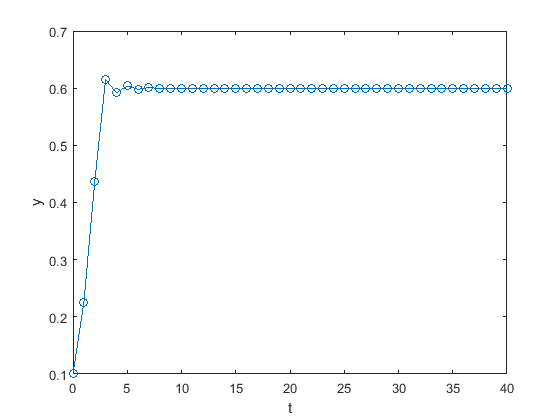

r = 2.5;
y(1) = 0.1;

#### c. Create a for loop to iterate the model 40 times

t_vals = [0:40];
for t=1:40
    y(t+1) = F(r, y(t));
end;

#### d. Produce a plot displaying changes of y(t) over t

plot(t_vals, y, "-o")

#### e. Name x-axis as "t" and y-axis as "y"

xlabel("t")
ylabel("y")

## Question 2

Produce a bifurcation diagram for the model in Question 1

#### a. Define a vector rv storing r values between 0.5 to 4

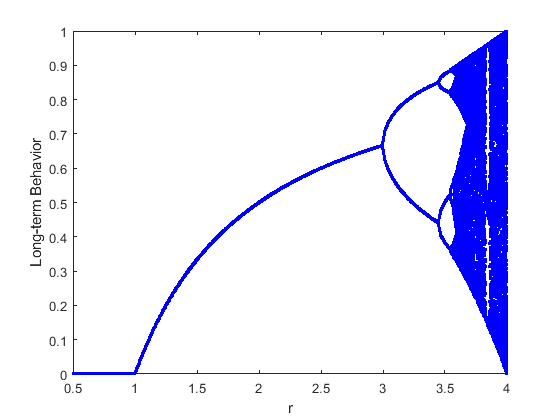

rv = linspace(0.5, 4, 1000);

long_term = [];

#### b. Solve the model 400 times for each value in rv

for i=1:1000
    
    r = rv(i);
    y(1) = 0.1;
    
  for t=1:400
    y(t+1) = F(r,y(t));
  end;
  
  long_term(i,:) = y(end-100:end);
  
end;

#### c. Extract the last 100 values of y from each run

y(end-100:end);

#### d. Produce a plot showing how the last 100 y-value changes as rv value increases

plot(rv, long_term, "b.")
xlabel("r")
ylabel("Long-term Behavior")